clear 
clc
%假设模型存在是这样子,传入f0 f1 和任意两个信号发射的点
% 之后调整接受信号无人机的位置,使得,a1 a2合乎要求
r = [100 98 112 105 98 112 105 98 112];
theta = [0 40.10 80.21 119.75 159.86 199.96 240.07 280.17 320.28];
x = r.*cos(theta)

x =   100.0000  -72.3233   11.1131   97.9141  -91.6755   50.6100   27.1799  -82.5985  110.5254


y = r.*sin(theta)

y =          0   66.1312 -111.4473   37.9186   34.6352  -99.9131  101.4212  -52.7398  -18.1146


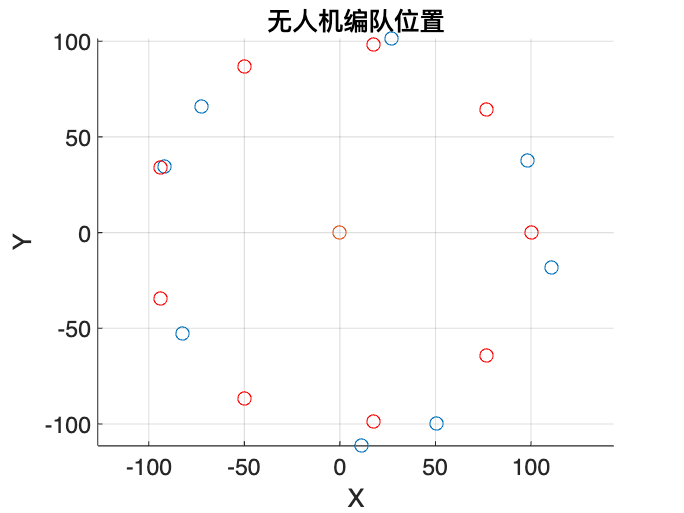


figure
hold on
axis equal;
scatter(x,y)
scatter(0,0)
grid on;
xlabel('X');
ylabel('Y');
title('无人机编队位置');

% 标记无人机
% text(x, y, {'FY01_', 'FY02_', 'FY03_', 'FY04_', 'FY05_', 'FY06_', 'FY07_', 'FY08_', 'FY09_'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
% text(0, 0, 'FY00', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

R = 100; % 圆形编队的半径
angles = linspace(0, 2*pi, 10); % 生成10个点的角度，包括起点和终点
angles = angles(1:end-1); % 移除终点，以避免与起点重合

% 计算无人机在圆周上的位置
x1 = R * cos(angles);
y1 = R * sin(angles);

% 绘制无人机的位置

plot(x1, y1, 'ro'); % 圆周上的无人机

% 标记无人机
% text(x1, y1, {'FY01', 'FY02', 'FY03', 'FY04', 'FY05', 'FY06', 'FY07', 'FY08', 'FY09'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
% text(0, 0, 'FY00', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

hold off